data_summary_csv = '/Users/pingchuanma/Documents/MATLAB/Publication/Fluorescence lifetim enables high-resolution analysis of neuromodulator dynamics across time and animals/Pingchuan_RvR_data_code/Scatter Plot (Raw)_grouped_no1627_20230115.csv';
summary_path = '/Users/pingchuanma/Documents/MATLAB/Publication/'

summary_path = '/Users/pingchuanma/Documents/MATLAB/Publication/'

data_summary = readtable(data_summary_csv, 'NumHeaderLines', 1)

data_summary = 589×7 table
              Var1               Var2    Var3    Var4       Var5        Var6      Var7 
    _________________________    ____    ____    ____    __________    ______    ______

    {'20220331_1611_RvR_001'}    1611     2       0      1.5463e+05     2.479    4.2278
    {'20220331_1611_RvR_001'}    1611     2       0       1.549e+05    2.4825    4.2288
    {'20220331_1611_RvR_001'}    1611     2       0      1.6125e+05    2.5064    4.2503
    {'20220331_1611_RvR_001'}    1611     2       0      1.5129e+05    2.4856    4.2317
    {'20220331_1611_RvR_001'}    1611     2       0      1.4984e+05    2.4788    4.2247
    {'20220331_1611_RvR_001'}    1611     2       0      1.5829e+05    2.5024    4.2506
    {'20220331_1611_RvR_001'} 

Mouse_ID = table2array(data_summary(:,2))

Mouse_ID =         1611
        1611
        1611
        1611
        1611
        1611
        1611
        1611
        1611
        1611


Laser = table2array(data_summary(:,3))

Laser =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


Speed = table2array(data_summary(:,4))

Speed =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


lft =     4.2278
    4.2288
    4.2503
    4.2317
    4.2247
    4.2506
    4.2237
    4.2250
    4.2250
    4.2431


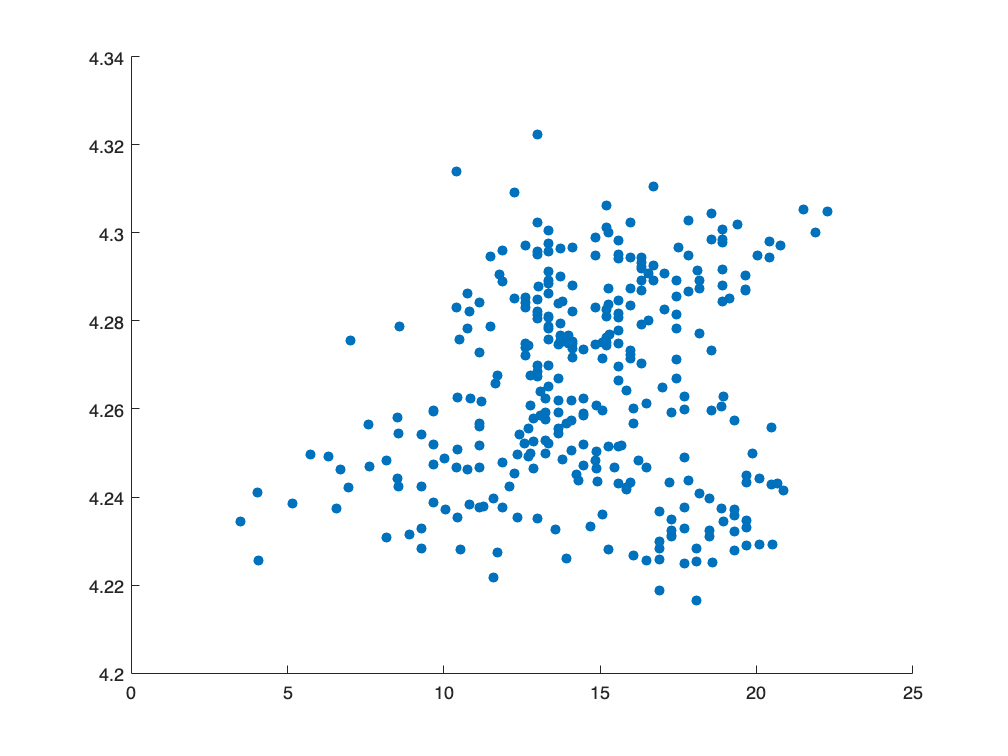

rho = 0.1400

p = 0.0115

intensity = table2array(data_summary(:,5))/100000;
lft = table2array(data_summary(:,7))

Mouse_ID_categorical = categorical(Mouse_ID)

Mouse_ID_categorical = 589×1 categorical array
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 
     1611 


Laser_categorical = categorical(Laser);
States =  zeros(length(Speed),1);
Running_index = [];

for i = 1:length(Speed)
    if Speed(i,1) > 0
        States(i) = 1;
        Running_index = [Running_index i];
    end
end

States_categorical = categorical(States);

mouse_all = categories(Mouse_ID_categorical)

mouse_all = 6×1 cell array
    {'1610'}
    {'1611'}
    {'1612'}
    {'1626'}
    {'1629'}
    {'1630'}


laser_all = categories(Laser_categorical)

laser_all = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


States_all = categories(States_categorical)

States_all = 2×1 cell array
    {'0'}
    {'1'}


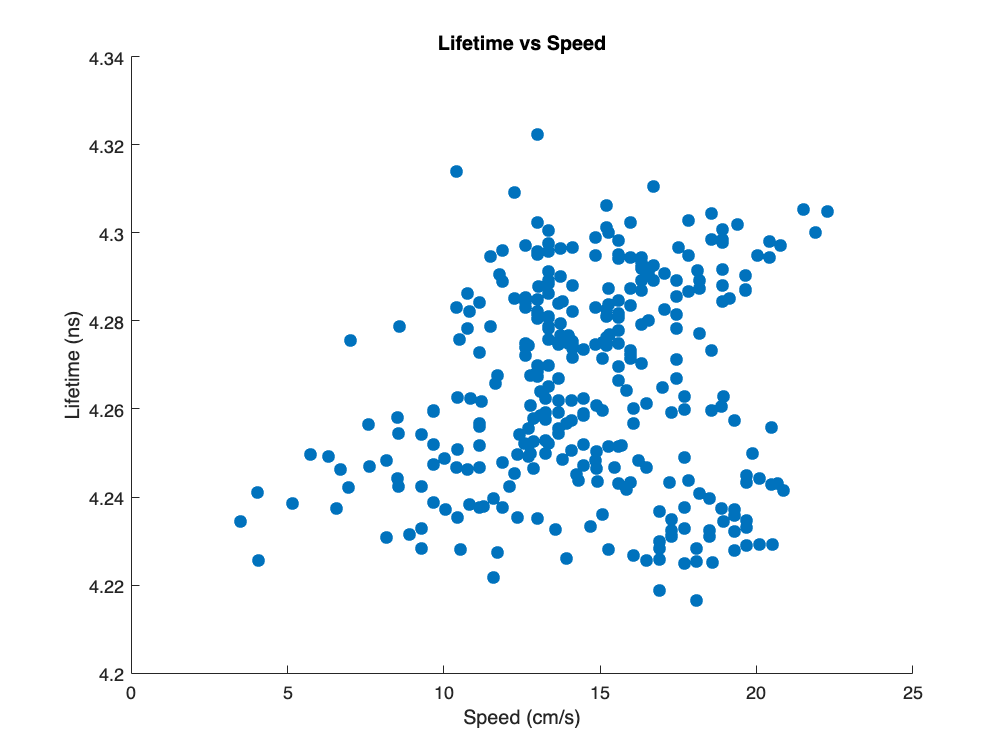

Speed_running = Speed(Running_index);
lft_running = lft(Running_index);

figure
scatter(Speed(Running_index), lft(Running_index), 50, 'filled')
xlabel('Speed (cm/s)')
ylabel('Lifetime (ns)')
title('Lifetime vs Speed')

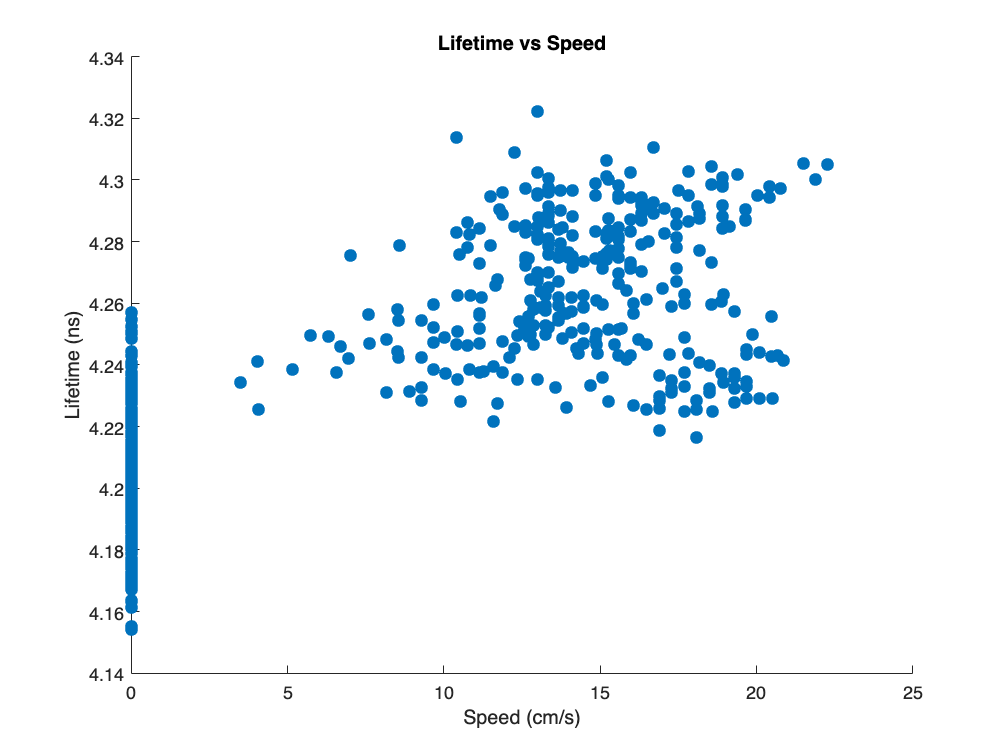

figure
scatter(Speed, lft, 50, 'filled')
xlabel('Speed (cm/s)')
ylabel('Lifetime (ns)')
title('Lifetime vs Speed')

[rho, p] = corr(Speed(Running_index), lft(Running_index))

d_intensity_resting = intensity(find(States == 0));
d_intensity_running = intensity(find(States == 1));

d_lft_resting = lft(find(States == 0));
d_lft_running = lft(find(States == 1));


lft_tbl = table(States_categorical, Mouse_ID_categorical, Laser_categorical, lft)

lft_tbl = 589×4 table
    States_categorical    Mouse_ID_categorical    Laser_categorical          lft       
    __________________    ____________________    _________________    ________________

            0                     1611                    2            4.22782464334963
            0                     1611                    2            4.22879834413091
            0                     1611                    2            4.25031509133775
            0                     1611                    2             4.2316624642122
            0                     1611                    2            4.22471499044789
            0                     1611                    2            4.25059226498943
            0                     1611                    2            4.22368470764861
            0                     1611           

mdl1=stepwiseglm(lft_tbl,'constant', 'Upper', 'interactions','Criterion','adjrsquared')

1. Adding States_categorical, AdjRsquared = 0.65514
2. Adding Laser_categorical, AdjRsquared = 0.87171
3. Adding Mouse_ID_categorical, AdjRsquared = 0.8903
4. Adding Mouse_ID_categorical:Laser_categorical, AdjRsquared = 0.92507
5. Adding States_categorical:Mouse_ID_categorical, AdjRsquared = 0.93785
6. Adding States_categorical:Laser_categorical, AdjRsquared = 0.93862


mdl1 = Generalized linear regression model:
    lft ~ 1 + States_categorical*Mouse_ID_categorical + States_categorical*Laser_categorical + Mouse_ID_categorical*Laser_categorical
    Distribution = Normal

Estimated Coefficients:
                                                            Estimate                  SE                   tStat                  pValue       
                                                      ____________________    ___________________    __________________    ____________________

    (Intercept)                                           4.19368121232155    0.00189083485577292      2217.89925202499                       0
    States_categorical_1                                0.0570077582532474    0.00236089012558027      24.1467223042562    5.93328392086087e-89
    Mouse_ID_cat

intensity_tbl = table(States_categorical, Mouse_ID_categorical, Laser_categorical, intensity)

intensity_tbl = 589×4 table
    States_categorical    Mouse_ID_categorical    Laser_categorical    intensity
    __________________    ____________________    _________________    _________

            0                     1611                    2             1.54627 
            0                     1611                    2             1.54896 
            0                     1611                    2             1.61254 
            0                     1611                    2            1.512915 
            0                     1611                    2             1.49838 
            0                     1611                    2            1.582935 
            0                     1611                    2            1.497995 
            0                     1611                    2            1.503445 
            0            

mdl2=stepwiseglm(intensity_tbl,'constant', 'Upper','Linear','Criterion','adjrsquared')

1. Adding Mouse_ID_categorical, AdjRsquared = 0.63801
2. Adding Laser_categorical, AdjRsquared = 0.89926
3. Adding States_categorical, AdjRsquared = 0.91254


mdl2 = Generalized linear regression model:
    intensity ~ 1 + States_categorical + Mouse_ID_categorical + Laser_categorical
    Distribution = Normal

Estimated Coefficients:
                                     Estimate                 SE                  tStat                 pValue        
                                 _________________    __________________    _________________    _____________________

    (Intercept)                   4.15000206431345    0.0539124977170511     76.9766239749065    1.21587307418563e-306
    States_categorical_1         0.375002378203472    0.0396920285925388     9.44780076758192      8.3987455219888e-20
    Mouse_ID_categorical_1611    -1.93824606264311    0.0702860600855342    -27.5765359487268    1.35693003397158e-107
    Mouse_ID_categorical_1612

lft_running=lft(find(States==1));
lft_resting=lft(find(States==0));

intensity_running=intensity(find(States==1));
intensity_resting=intensity(find(States==0));

intensity_collection=[];
lft_collection=[];
mouseID_collection=[];
laser_collection=[];
states_collection=[];

for i=1:7
    mouse=mouse_all(i)
    

    lft_mouse=lft(find(Mouse_ID_categorical == mouse));
    intensity_mouse=intensity(find(Mouse_ID_categorical == mouse));
    speed_mouse=Speed(find(Mouse_ID_categorical == mouse));
    laser_mouse=Laser(find(Mouse_ID_categorical == mouse));
    states_mouse=States(find(Mouse_ID_categorical == mouse));

    eval(['lft_',convertStringsToChars(cell2mat(mouse)),'=lft_mouse;'])
    eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'=intensity_mouse;'])
    eval(['speed_',convertStringsToChars(cell2mat(mouse)),'=speed_mouse;'])
    eval(['laser_',convertStringsToChars(cell2mat(mouse)),'=laser_mouse;'])
    eval(['states_',convertStringsToChars(cell2mat(mouse)),'=states_mouse;'])

    for j=1:3

        lft_mouse_laser=lft_mouse(find(laser_mouse==j));
        intensity_mouse_laser=intensity_mouse(find(laser_mouse==j));
        speed_mouse_laser=speed_mouse(find(laser_mouse==j));
        states_mouse_laser=states_mouse(find(laser_mouse==j));
        lft_mouse_laser_running=lft_mouse_laser(find(states_mouse_laser==1));
        lft_mouse_laser_resting=lft_mouse_laser(find(states_mouse_laser==0));
        intensity_mouse_laser_running=intensity_mouse_laser(find(states_mouse_laser==1));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;j];
        states_collection=[states_collection;[1]];
        if isempty(intensity_mouse_laser_running)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_running)];
        end

        if isempty(lft_mouse_laser_running)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_running)];
        end

        intensity_mouse_laser_resting=intensity_mouse_laser(find(states_mouse_laser==0));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;[j]];
        states_collection=[states_collection;[0]];
        if isempty(intensity_mouse_laser_resting)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_resting)];
        end

        if isempty(lft_mouse_laser_resting)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_resting)];
        end

      
        

        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=lft_mouse_laser;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=intensity_mouse_laser;'])
        eval(['speed_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=speed_mouse_laser;'])
        eval(['states_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=states_mouse_laser;'])

        lft_mouse_laser_running = [lft_mouse_laser_running;NaN(100-length(lft_mouse_laser_running), 1)];
        lft_mouse_laser_resting = [lft_mouse_laser_resting;NaN(100-length(lft_mouse_laser_resting), 1)];
        intensity_mouse_laser_running = [intensity_mouse_laser_running;NaN(100-length(intensity_mouse_laser_running), 1)];
        intensity_mouse_laser_resting = [intensity_mouse_laser_resting;NaN(100-length(intensity_mouse_laser_resting), 1)];
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=lft_mouse_laser_running;'])
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=lft_mouse_laser_resting;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=intensity_mouse_laser_running;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=intensity_mouse_laser_resting;'])
    end

end

mouse = 1×1 cell array
    {'1610'}


mouse = 1×1 cell array
    {'1611'}


mouse = 1×1 cell array
    {'1612'}


mouse = 1×1 cell array
    {'1626'}


mouse = 1×1 cell array
    {'1627'}


mouse = 1×1 cell array
    {'1629'}


mouse = 1×1 cell array
    {'1630'}



FYI=[mouseID_collection laser_collection states_collection intensity_collection lft_collection];

for i = 1:7
    mouse=convertStringsToChars(cell2mat(mouse_all(i)));
    mouse_intensity_AllLaser = NaN(3,100);
    mouse_lft_AllLaser = NaN(3,100);

    for j = 1:3

        eval(['intensity_this_mousepower_resting = intensity_', mouse, '_', num2str(j),'_resting;'])
        eval(['intensity_this_mousepower_running = intensity_', mouse, '_', num2str(j),'_running;'])
        eval(['lft_this_mousepower_resting = lft_', mouse, '_', num2str(j),'_resting;'])
        eval(['lft_this_mousepower_running = lft_', mouse, '_', num2str(j),'_running;'])

        if isempty(intensity_this_mousepower_resting) == 0
            mouse_intensity_AllLaser(j,1:length(intensity_this_mousepower_resting)) = intensity_this_mousepower_resting;
            mouse_intensity_AllLaser(j,51:50+length(intensity_this_mousepower_running)) = intensity_this_mousepower_running;
            mouse_lft_AllLaser(j,1:length(lft_this_mousepower_resting)) = lft_this_mousepower_resting;
            mouse_lft_AllLaser(j,51:50+length(lft_this_mousepower_running)) = lft_this_mousepower_running;
        end
    end

    eval(['a_', mouse, '_intensity_AllLaser = mouse_intensity_AllLaser;'])
    eval(['a_', mouse, '_lft_AllLaser = mouse_lft_AllLaser;'])
end

for i = 1:3
    
    power = ['power',num2str(i)];
    laser_intensity_AllMice = NaN(7,100);
    laser_lft_AllMice = NaN(7,100);

    for j = 1:7
        mouse=convertStringsToChars(cell2mat(mouse_all(j)));

        eval(['intensity_this_mousepower_resting = intensity_', mouse, '_', num2str(i),'_resting;'])
        eval(['intensity_this_mousepower_running = intensity_', mouse, '_', num2str(i),'_running;'])
        eval(['lft_this_mousepower_resting = lft_', mouse, '_', num2str(i),'_resting;'])
        eval(['lft_this_mousepower_running = lft_', mouse, '_', num2str(i),'_running;'])

        if isempty(intensity_this_mousepower_resting) == 0
            laser_intensity_AllMice(j,1:length(intensity_this_mousepower_resting)) = intensity_this_mousepower_resting;
            laser_intensity_AllMice(j,51:50+length(intensity_this_mousepower_running)) = intensity_this_mousepower_running;
            laser_lft_AllMice(j,1:length(lft_this_mousepower_resting)) = lft_this_mousepower_resting;
            laser_lft_AllMice(j,51:50+length(lft_this_mousepower_running)) = lft_this_mousepower_running;
        end
    end

    eval(['b_', power, '_intensity_AllMice = laser_intensity_AllMice;'])
    eval(['b_', power, '_lft_AllMice = laser_lft_AllMice;'])
end

c_intensity_resting_all = [];
c_intensity_running_all = [];
c_lft_resting_all = [];
c_lft_running_all = [];

for i = 1:7
    mouse=convertStringsToChars(cell2mat(mouse_all(i)));
    c_intensity_resting = [];
    c_intensity_running = [];
    c_lft_resting = [];
    c_lft_running = [];

    for j = 1:3
        eval(['c_intensity_resting = [c_intensity_resting; intensity_', mouse, '_', num2str(j), '_resting];' ])
        eval(['c_intensity_running = [c_intensity_running; intensity_', mouse, '_', num2str(j), '_running];' ])
        eval(['c_lft_resting = [c_lft_resting; lft_', mouse, '_', num2str(j), '_resting];' ])
        eval(['c_lft_running = [c_lft_running; lft_', mouse, '_', num2str(j), '_running];' ])
    end

    eval(['c_' mouse, '_intensity_resting = c_intensity_resting;'])
    eval(['c_' mouse, '_intensity_running = c_intensity_running;'])
    eval(['c_' mouse, '_lft_resting = c_lft_resting;'])
    eval(['c_' mouse, '_lft_running = c_lft_running;'])

    c_intensity_resting_all = [c_intensity_resting_all c_intensity_resting];
    c_intensity_running_all = [c_intensity_running_all c_intensity_running];
    c_lft_resting_all = [c_lft_resting_all c_lft_resting];
    c_lft_running_all = [c_lft_running_all c_lft_running];
end


csvwrite('RvR_mean_summary_20221219.csv', FYI)

% This part remove the 1627 data from the pooled resting vs running summary
index_1627 = find(Mouse_ID == 1627);

intensity_no1627 = intensity;
lft_no1627 = lft;
States_no1627 = States;

intensity_no1627(index_1627) = [];
lft_no1627(index_1627) = [];
States_no1627(index_1627) = [];

d_intensity_resting_no1627 = intensity_no1627(find(States_no1627 == 0));
d_intensity_running_no1627 = intensity_no1627(find(States_no1627 == 1));

d_lft_resting_no1627 = lft_no1627(find(States_no1627 == 0));
d_lft_running_no1627 = lft_no1627(find(States_no1627 == 1));